## **Visualisation des différentes configurations du robot pour suivre une trajectoire**

Ce code permet, après definition des variables, des longueurs des bras du robot, de la position desiree de l'effecteur, du nombre de solution souhaités affichées, et des butées de chaque articulation, de générer l'espace de travail du robot, puis de le visualiser dans les configurations possibles pour atteindre le point désiré par résolution de la cinmeatique inverse par la méthode variationnelle. 

### **Definition des variables**

% Définir les symboles pour les angles d'articulation
syms theta1 theta2 theta3 theta4;

% Définir les longueurs des bras
a1 = 2; % Longueur du premier bras
a2 = 3; % Longueur du deuxième bras
a3 = 2; % Longueur du troisième bras
a4 = 2; % Longueur du quatrieme bras
a5 = 2; % Longueur du cinquieme bras


theta1_min = -90;
theta1_max = 90;
theta2_min = -95;
theta2_max = 95;
theta3_min = -90;
theta3_max = 90;
theta4_min = -90;
theta4_max = 90;
theta5_min = -90;
theta5_max = 90;

% Stocker les valeurs dans la matrice butee
butee = [theta1_min, theta1_max; theta2_min, theta2_max; theta3_min, theta3_max; theta4_min, theta4_max; theta5_min, theta5_max];
% Enregistrement de la matrice dans un fichier .mat
save('butee.mat', 'butee');
% Convertir les limites des intervalles de degrés en radians
butee_rad = deg2rad(butee);

num_configurations = 10;


### Definition de la trajectoire

% Définir la trajectoire souhaitée (par exemple, un cercle)
num_points = 10;
radius = 9;
theta_traj = linspace(0, pi/3, num_points);
x_traj = radius * cos(theta_traj);
y_traj = radius * sin(theta_traj);
% Combiner les coordonnées x et y en une seule matrice de points de trajectoire
trajectory_points = [x_traj', y_traj'];
% Afficher les points de la trajectoire sous forme de tableau
disp('Points de la trajectoire :');

Points de la trajectoire :


fprintf('-------------------------------------------------\n');

-------------------------------------------------


fprintf('| Point  |      X     |      Y     |\n');

| Point  |      X     |      Y     |


fprintf('-------------------------------------------------\n');

-------------------------------------------------


for i = 1:num_points
    fprintf('|   %2d   |   %7.2f   |   %7.2f   |\n', i, x_traj(i), y_traj(i));
end

|    1   |      9.00   |      0.00   |
|    2   |      8.94   |      1.04   |
|    3   |      8.76   |      2.08   |
|    4   |      8.46   |      3.08   |
|    5   |      8.04   |      4.04   |
|    6   |      7.52   |      4.95   |
|    7   |      6.89   |      5.79   |
|    8   |      6.18   |      6.55   |
|    9   |      5.37   |      7.22   |
|   10   |      4.50   |      7.79   |


fprintf('-------------------------------------------------\n')

-------------------------------------------------




% Afficher la trajectoire
figure;
plot(x_traj, y_traj, 'r-', 'LineWidth', 1.5, 'DisplayName', 'Trajectoire à suivre' );
axis equal; % Pour que l'échelle des axes soit égale
xlabel('X');
ylabel('Y');
title('Trajectoire');
grid on;
hold on;

### Affichage de l'espace de travail : 

- liste pour **stocker les coordonnees atteignables,**

- definition de l**'echantillon d'angles testés et du pas**

% Initialiser une liste pour stocker les coordonnées atteignables
reachable_points = [];

% % Définir la grille d'angles d'articulation
theta1_range = linspace(butee_rad(1, 1), butee_rad(1, 2), 6);
theta2_range = linspace(butee_rad(2, 1), butee_rad(2, 2), 6);
theta3_range = linspace(butee_rad(3, 1), butee_rad(3, 2), 6);
theta4_range = linspace(butee_rad(4, 1), butee_rad(4, 2), 6);
theta5_range = linspace(butee_rad(5, 1), butee_rad(5, 2), 6);
% % Nombre de pas pour chaque articulation
% step_angle = 15; % Espacement entre chaque angle en degrés

- **calcul des coordonnees atteignables** pour chaque combinaison d'angles possibles de l'echantillon, par **cinematique directe**

% Calculer les coordonnées atteignables pour chaque combinaison d'angles
for i = 1:length(theta1_range)
    for j = 1:length(theta2_range)
        for k = 1:length(theta3_range)
            for l = 1:length(theta4_range)
                for m = 1:length(theta5_range)
                    % Calculer les coordonnées de l'effecteur
                    x = a1 * cos(theta1_range(i)) + a2 * cos(theta1_range(i) + theta2_range(j)) + a3 * cos(theta1_range(i) + theta2_range(j) + theta3_range(k)) + a4 * cos(theta1_range(i) + theta2_range(j) + theta3_range(k) + theta4_range(l)) + a5 * cos(theta1_range(i) + theta2_range(j) + theta3_range(k) + theta4_range(l) + theta5_range(m));
                    y = a1 * sin(theta1_range(i)) + a2 * sin(theta1_range(i) + theta2_range(j)) + a3 * sin(theta1_range(i) + theta2_range(j) + theta3_range(k)) + a4 * sin(theta1_range(i) + theta2_range(j) + theta3_range(k) + theta4_range(l)) + a5 * sin(theta1_range(i) + theta2_range(j) + theta3_range(k) + theta4_range(l) + theta5_range(m));
                     % Ajouter les coordonnées à la liste
                    reachable_points = [reachable_points; x, y];
                end
            end
        end
    end
end

points_atteign = [reachable_points(:, 1), reachable_points(:, 2)];


- affichage des **contours de l'espace de travail**

% % Calculer les contours convexes du nuage de points avec une méthode plus précise
K = convhull(points_atteign);

% % Tracer les contours de l'espace de travail
plot(points_atteign(K, 1), points_atteign(K, 2), 'b', 'LineWidth', .5, 'DisplayName', 'Contours de l''espace de travail');
fill(points_atteign(K, 1), points_atteign(K, 2), 'b', 'FaceAlpha', 0.1, 'EdgeColor', 'none', 'DisplayName', 'Espace de travail');

% Mettre à jour le graphique
title('Position du robot' );
xlabel('X');
ylabel('Y');
axis equal; % Assure que les proportions X/Y sont égales
grid on;
legend show;
legend("Position", [0.58731,0.15829,0.38571,0.11905])

hold on;

### Resolution IK après vérification de l'appartenance du point cible à l'espace de travail (revoir la verif)

Cette partie procède tout d'abord à une verification de l'appartenance du point désiré de l'effecteur à l'esapce de travail du robot. Si cela est vérifé on lance alors le calcul de cinématique inverse par la méthode variationnelle. 

Puis on affiche les solutions , d'abord en raidan et ensuite en degrès.


% Initialiser une matrice pour stocker les résultats finaux
final_results = [];

% Paramètres de l'algorithme d'ajustement du rayon
max_iterations = 10;
tolerance = 1;
adjusted_radius = zeros(1, num_points); % Vecteur pour stocker les rayons actualisés

% Itérer sur chaque point de la trajectoire
for i = 1:num_points
    % Initialiser le rayon avec le rayon d'origine
    current_radius = radius;
    % Initialiser le nombre d'itérations
    iterations = 0;
    
    % Itération jusqu'à ce que le point soit à l'intérieur de l'espace de travail ou que le nombre maximal d'itérations soit atteint
    while iterations < max_iterations
        % Calculer les coordonnées du point de la trajectoire avec le rayon actuel
        x_desired = current_radius * cos(theta_traj(i));
        y_desired = current_radius * sin(theta_traj(i));
        
        % Vérifier si le point désiré se trouve dans l'espace de travail
        if point_in_workspace(x_desired, y_desired, points_atteign, K)
            % Si le point est à l'intérieur de l'espace de travail, sortir de la boucle
            break;
        else
            % Si le point est à l'extérieur de l'espace de travail, ajuster le rayon
            current_radius = current_radius - tolerance;
            iterations = iterations + 1;
        end
    end
    
    % Enregistrer le rayon actualisé dans le vecteur
    adjusted_radius(i) = current_radius;
    
    % Si le nombre maximal d'itérations est atteint sans trouver une solution satisfaisante, afficher un avertissement
    if iterations == max_iterations
        warning('Impossible d''ajuster le rayon pour que le point de la trajectoire %d soit à l''intérieur de l''espace de travail.', i);
    end
    
    % Appeler la fonction de cinématique inverse pour trouver les solutions pour ce point
    
    all_solutions = find_inverse_kinematics(a1, a2, a3, a4, a5, x_desired, y_desired, num_configurations);

    % Ajouter une colonne pour le numéro du point de trajectoire
    point_numbers = repmat(i, size(all_solutions, 1), 1);
    all_solutions_with_point_numbers = [point_numbers, all_solutions];

    % Ajouter les résultats à la matrice finale
    final_results = [final_results; all_solutions_with_point_numbers];
end

% Enregistrer les résultats dans un fichier
save('solutionstraj.mat', 'final_results');

% Afficher le rayon actualisé
fprintf('Rayon actualisé pour la trajectoire :\n');

Rayon actualisé pour la trajectoire :


fprintf('%s\n', num2str(adjusted_radius));

9  9  9  9  9  9  9  9  9  9



% Afficher le tableau final
fprintf('-----------------------------------------------------------------------------\n');

-----------------------------------------------------------------------------


fprintf('| Point  | Theta1   | Theta2   | Theta3   | Theta4   | Theta5   | X_calculé | Y_calculé |\n');

| Point  | Theta1   | Theta2   | Theta3   | Theta4   | Theta5   | X_calculé | Y_calculé |


fprintf('-----------------------------------------------------------------------------\n');

-----------------------------------------------------------------------------


for row = 1:size(final_results, 1)
    fprintf('|   %2d   | %8.2f | %8.2f | %8.2f | %8.2f | %8.2f | %9.2f | %9.2f |\n', final_results(row, :));
end

|    1   |     0.33 |     4.93 |     1.53 |     6.23 |     5.82 |      9.00 |      0.00 |
|    1   |     5.53 |     1.04 |     5.92 |     5.82 |     1.62 |      9.00 |     -0.00 |
|    1   |     0.63 |     5.14 |     1.53 |     4.86 |     0.05 |      9.00 |      0.00 |
|    1   |     0.53 |     5.14 |     1.24 |     6.15 |     5.02 |      9.00 |     -0.00 |
|    1   |     5.08 |     1.01 |     0.86 |     6.08 |     5.98 |      9.00 |      0.00 |
|    1   |     0.30 |     4.94 |     1.61 |     5.96 |     6.25 |      9.00 |     -0.00 |
|    1   |     0.24 |     5.12 |     1.55 |     6.24 |     5.51 |      9.00 |     -0.00 |
|    1   |     5.17 |     0.87 |     0.98 |     6.07 |     5.83 |      9.00 |      0.00 |
|    1   |     6.25 |     5.59 |     1.86 |     5.39 |     5.88 |      9.00 |      0.00 |
|    1   |     0.11 |     5.24 |     1.54 |     0.05 |     5.52 |      9.00 |     -0.00 |
|    2   |     5.93 |     1.05 |     0.12 |     5.36 |     5.60 |      8.94 |      1.04 |
|    2   |

fprintf('-----------------------------------------------------------------------------\n');

-----------------------------------------------------------------------------


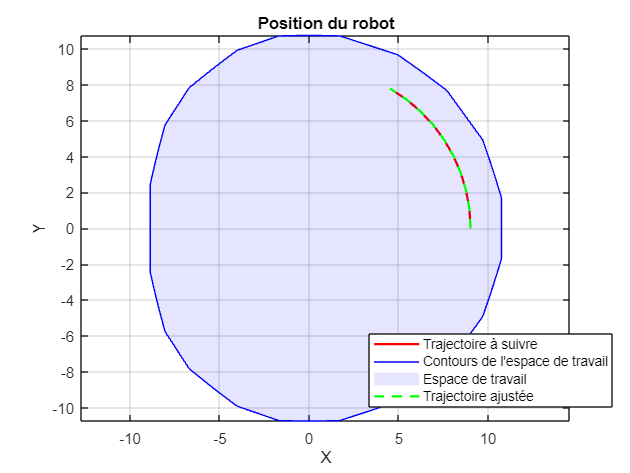

% Afficher la trajectoire avec le rayon ajusté
x_traj_adjusted = adjusted_radius .* cos(theta_traj);
y_traj_adjusted = adjusted_radius .* sin(theta_traj);

% Tracer la nouvelle trajectoire avec le rayon ajusté sur la même figure
hold on;
plot(x_traj_adjusted, y_traj_adjusted, 'g--', 'LineWidth', 1.5, 'DisplayName', 'Trajectoire ajustée');


% Mettre à jour le graphique
legend show;


function in_workspace = point_in_workspace(x, y, points_atteign, K)
    % Vérifie si le point (x, y) est dans l'espace de travail du robot
    in_workspace = inpolygon(x, y, points_atteign(K, 1), points_atteign(K, 2));
end

function [all_solutions] = find_inverse_kinematics(a1, a2, a3, a4, a5, x_desired, y_desired, num_configurations)

    % Définir les angles d'articulation
    syms theta1 theta2 theta3 theta4 theta5;

    % Définir une tolérance et un nombre maximum d'itérations
    tolerance = 0.0000001;
    max_iterations = 100;
    
    % Initialiser une liste pour stocker les configurations atteignables
    all_solutions = [];
    point_number = [];
    % Recherche des configurations
    while size(all_solutions, 1) < num_configurations
        
        % Initialiser les angles d'articulation en fonction des butées
        % Générer des angles d'articulation aléatoires entre 0 et 2*pi radians
        theta1 = rand * 2*pi;
        theta2 = rand * 2*pi;
        theta3 = rand * 2*pi;
        theta4 = rand * 2*pi;
        theta5 = rand * 2*pi;

        % Boucle d'itération pour trouver les angles d'articulation
        for i = 1:max_iterations
            % Calculer les équations directes de cinématique directe
            x = a1*cos(theta1) + a3*cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - a3*sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + a2*cos(theta1)*cos(theta2) - a2*sin(theta1)*sin(theta2) + a5*cos(theta5)*(cos(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1))) - sin(theta4)*(cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)))) + a4*cos(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1))) - a5*sin(theta5)*(cos(theta4)*(cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2))) + sin(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)))) - a4*sin(theta4)*(cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)));
            y = a1*sin(theta1) + a3*cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + a3*sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) + a2*cos(theta1)*sin(theta2) + a2*cos(theta2)*sin(theta1) + a5*cos(theta5)*(cos(theta4)*(cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2))) + sin(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)))) + a4*cos(theta4)*(cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2))) + a5*sin(theta5)*(cos(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1))) - sin(theta4)*(cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)))) + a4*sin(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)));
          
            % Calculer l'erreur de position
            error_x = x_desired - x;
            error_y = y_desired - y;
            error = [error_x; error_y];

            % Calculer les dérivées partielles
            dx_dtheta1 = -a1*sin(theta1) - a3*cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - a3*sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) - a2*sin(theta1)*sin(theta2) - a2*cos(theta1)*cos(theta2) - a4*sin(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1))) - a5*sin(theta5)*(cos(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1))) - sin(theta4)*(cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2))));
            dx_dtheta2 = -a3*cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - a3*sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + a2*cos(theta1)*cos(theta2) - a2*sin(theta1)*sin(theta2) - a4*sin(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1))) - a5*sin(theta5)*(cos(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1))) - sin(theta4)*(cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2))));
            dx_dtheta3 = a3*sin(theta3)*(sin(theta1)*sin(theta2) - cos(theta1)*cos(theta2)) + a4*sin(theta4)*(sin(theta1)*sin(theta2) - cos(theta1)*cos(theta2)) + a5*sin(theta5)*(sin(theta1)*sin(theta2) - cos(theta1)*cos(theta2));
            dx_dtheta4 = -a4*sin(theta4)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - a5*sin(theta5)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2));
            dx_dtheta5 = -a5*sin(theta5)*(cos(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1))) - sin(theta4)*(cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2))) + a5*cos(theta5)*(cos(theta4)*(cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2))) - sin(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)))));
    
            dy_dtheta1 = a1*cos(theta1) + a3*cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + a3*sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) + a2*cos(theta2)*sin(theta1) + a2*cos(theta1)*sin(theta2) + a4*cos(theta4)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) + a5*cos(theta5)*(cos(theta4)*(cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2))) + sin(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)))) + a5*sin(theta5)*(cos(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1))) - sin(theta4)*(cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2))));
            dy_dtheta2 = a3*cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + a3*sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - a2*sin(theta1)*sin(theta2) - a2*cos(theta1)*cos(theta2) - a4*sin(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1))) - a5*sin(theta5)*(cos(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1))) - sin(theta4)*(cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2))));
            dy_dtheta3 = - a3*sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + a4*sin(theta4)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + a5*sin(theta5)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1));
            dy_dtheta4 = - a4*sin(theta4)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) - a5*sin(theta5)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1));
            dy_dtheta5 = a5*cos(theta5)*(cos(theta4)*(cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2))) - sin(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1))) - a5*sin(theta5)*(cos(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1))) + sin(theta4)*(cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)))));
    
            % Construire la Jacobienne
            J = [dx_dtheta1, dx_dtheta2, dx_dtheta3, dx_dtheta4, dx_dtheta5; 
             dy_dtheta1, dy_dtheta2, dy_dtheta3, dy_dtheta4, dy_dtheta5];
    
            % Vérifier la convergence
            if norm(error) < tolerance
                %disp('Convergence atteinte.');
                % Stocker la solution
                all_solutions = [all_solutions; [theta1, theta2, theta3, theta4, theta5, x, y]];
                
                break;
            end

            % Calculer la variation des angles d'articulation
            delta_theta = pinv(J) * error;
    
            % Mise a jour des les angles d'articulation
            theta1 = theta1 + delta_theta(1);
            theta2 = theta2 + delta_theta(2);
            theta3 = theta3 + delta_theta(3);
            theta4 = theta4 + delta_theta(4);
            theta5 = theta5 + delta_theta(5);

            % Maintien des angles entre 0 et 2*pi
            theta1 = mod(theta1, 2*pi);
            theta2 = mod(theta2, 2*pi);
            theta3 = mod(theta3, 2*pi);
            theta4 = mod(theta4, 2*pi);
            theta5 = mod(theta5, 2*pi);
            % Incrémenter le numéro du point de la trajectoire
            point_number = point_number + 1;
        end
        
    end
end
